数据准备与清理

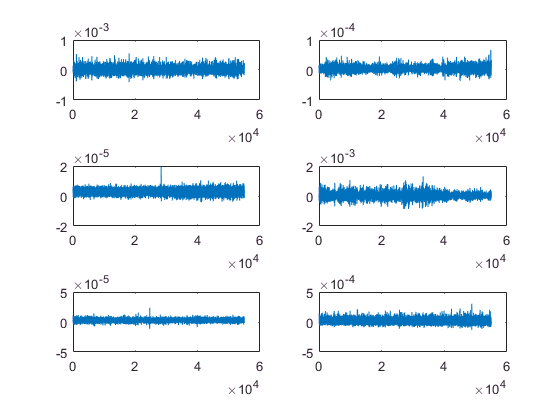

namePrefix = ['liziyou_semg1_'];
mvName = {'up', 'down', 'forward', 'backward', 'left', 'right'};
% 踝关节: up - down
% 膝关节: forward - backward
% 髋关节: left - right
figure;
for i =1:6
    dataPath = [namePrefix, mvName{i}, '.mat'];
    data = load(dataPath);
    subplot(3,2,i);
    plot(data.ch1(7001:62000))
    % [7001, 62000]
end

准备样本空间

RawData = {};
for i=1:6
    dataPath = [namePrefix, mvName{i}, '.mat'];
    data = load(dataPath);
    RawData{i} = [data.ch1(7001:62000)'; ...
                  data.ch2(7001:62000)'; ...
%                   data.ch3(7001:62000)'; ...
%                   data.ch4(7001:62000)'; ...
                  data.ch5(7001:62000)'; ...
%                   data.ch6(7001:62000)' ...
                  ];
end
% size(RawData)
% size(RawData{1})

addpath('../../../MATLAB/FeaturesExtraction');
fE.featuresCell = {'RMS', 'MAV', 'SSC', 'WL'};
fE.LW = 512;
fE.LI = 128;
sampleX = RawdataCell2SampleCellN(RawData, fE);
% size(sampleX{1})

% figure;
% plot(sampleX{1}(:, 1)); hold on;
% plot(sampleX{1}(:, 4)); 

使用class-LDA的分类模型

addpath('../../../MATLAB/DimensionReduction');
lda = LDA(6);
lda.SimpleTrainM(sampleX);
nRow = lda.Judge(sampleX{2}(1:10, :))

nRow =      6     1     6     6     1     1     1     1     6     1
